GAM = rand+1;
C = (GAM./(GAM-1));
clear GAM
rho = rand;
p = rand*100;
v = (2*rand-1);
ga = 1./sqrt(1-v.^2);
h = 1+C.*(p./rho);
D = rho.*ga;
m = rho.*h.*ga.^2.*v;
E = rho.*h.*ga.^2-p;
X = 0:1:100;
Y = (C.*X +m.^2./(E+X) + D.*sqrt(1-m.^2./(E+X).^2) - E-X);

% clf
% plot(X,Y/-C+X)
% hold on
% plot(X,X)
% plot(X,Y)
% plot(X,X-X)
clf
f = @(x)-(m^2./(E+x) + D.*sqrt(1-m.^2./(E+x).^2) - E-x)/C

f = 包含以下值的 function_handle :
    @(x)-(m^2./(E+x)+D.*sqrt(1-m.^2./(E+x).^2)-E-x)/C


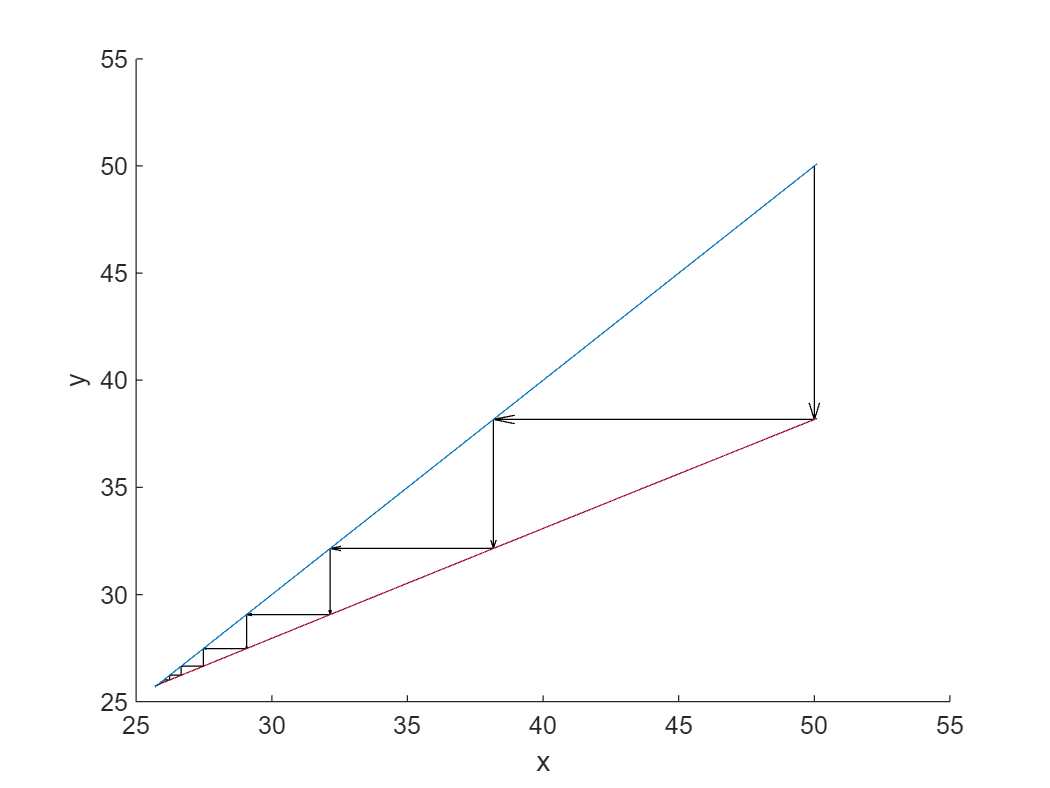

graphAnalysis(f,50,100)

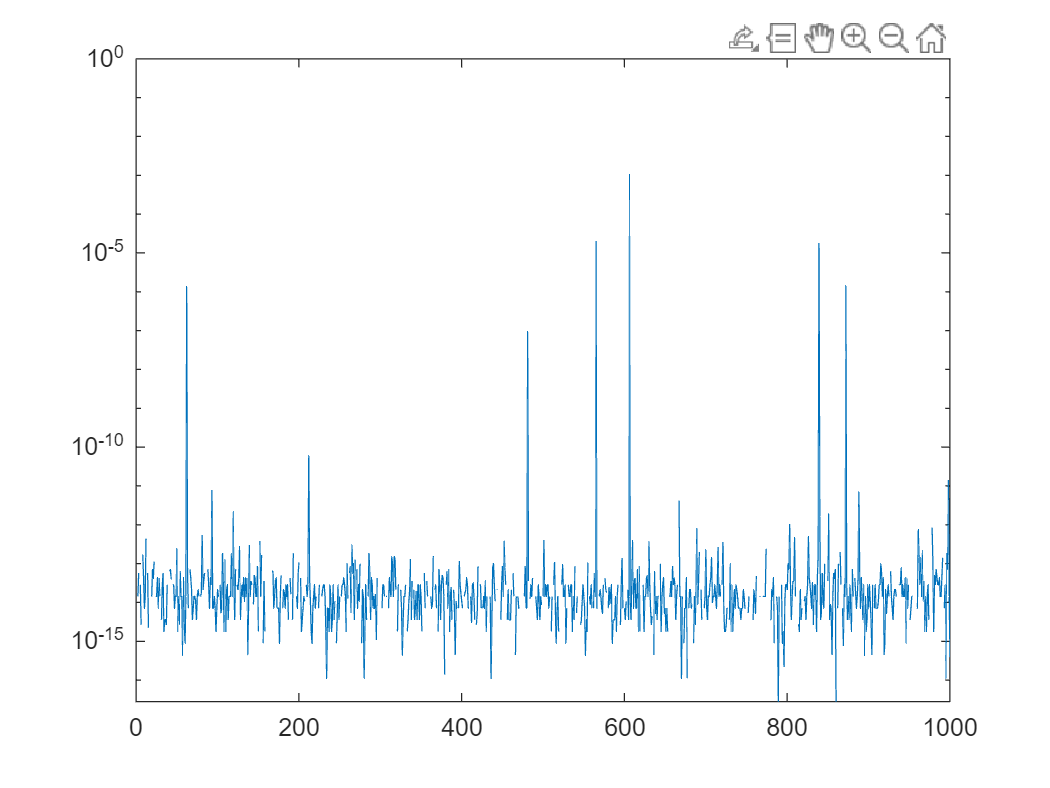

clc,clear
n = 1e3;
GAM = rand(n,1)+1;
C = (GAM./(GAM-1));
clear GAM
rho = rand(n,1);
p = rand(n,1)*100;
v = (2*rand(n,1)-1);
t = (2*rand(n,1)-1);
ga = 1./sqrt(1-v.^2);
h = 1+C.*(p./rho);
D = rho.*ga;
m = rho.*h.*ga.^2.*v;
E = rho.*h.*ga.^2-p;
Phi0 = m.^2./(E) + D.*sqrt(1-m.^2./(E).^2) - E;
X = -Phi0.*(C-1);

for k = 1:200
    X = -(m.^2./(E+X) + D.*sqrt(1-m.^2./(E+X).^2) - E-X)./C;
end
clf
semilogy(abs(X-p))

function graphAnalysis(f,x,t)
% f is the iteration function, remember to add '.'
% x is the initial values, x can be a vector
% t is the iteration times, where t starts from 0
clf
mini = x;% range
maxi = x;
for i = 0:t
    y = f(x);
    hold on;
    quiver(x,x,zeros(size(x)),y-x,'k',"AutoScale","off")
    quiver(x,y,y-x,zeros(size(x)),'k',"AutoScale","off")
    x = y;
    mini = min(x,mini);
    maxi = max(x,maxi);
end
hold on;
fplot(f,[min(mini)-0.1,max(maxi)+0.1]); %draw founction
hold on;
fplot(@(x)x,[min(mini)-0.1,max(maxi)+0.1]);%draw y=x
xlabel('x');
ylabel('y');
end